clf

e = 0; f = -1; g = 1; h = 0;
x_0 = 1; y_0 = 0;

T = 10

T = 10

N = 100

N = 100


[x,y,t] = IEMsolver(e,f,g,h,x_0,y_0,T,N)

A =      0    -1
     1     0


dt = 0.1000

x =     1.0000    0.9950    0.9800    0.9552    0.9208    0.8772    0.8248    0.7642    0.6958    0.6205    0.5390    0.4520    0.3606    0.2655    0.1677    0.0683   -0.0319   -0.1317   -0.2302   -0.3264   -0.4193   -0.5080   -0.5916   -0.6693   -0.7403   -0.8039   -0.8594   -0.9063   -0.9441   -0.9725   -0.9911   -0.9997   -0.9984   -0.9870   -0.9657   -0.9348   -0.8945   -0.8452   -0.7875   -0.7218   -0.6489   -0.5695   -0.4844   -0.3945   -0.3005   -0.2036   -0.1046   -0.0046    0.0955    0.1946


y =          0    0.1000    0.1990    0.2960    0.3900    0.4802    0.5655    0.6452    0.7184    0.7843    0.8425    0.8922    0.9329    0.9643    0.9860    0.9979    0.9997    0.9915    0.9734    0.9455    0.9081    0.8617    0.8066    0.7434    0.6727    0.5953    0.5120    0.4235    0.3307    0.2347    0.1362    0.0364   -0.0637   -0.1632   -0.2611   -0.3564   -0.4481   -0.5353   -0.6171   -0.6928   -0.7615   -0.8226   -0.8754   -0.9195   -0.9543   -0.9796   -0.9951   -1.0006   -0.9960   -0.9815


t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


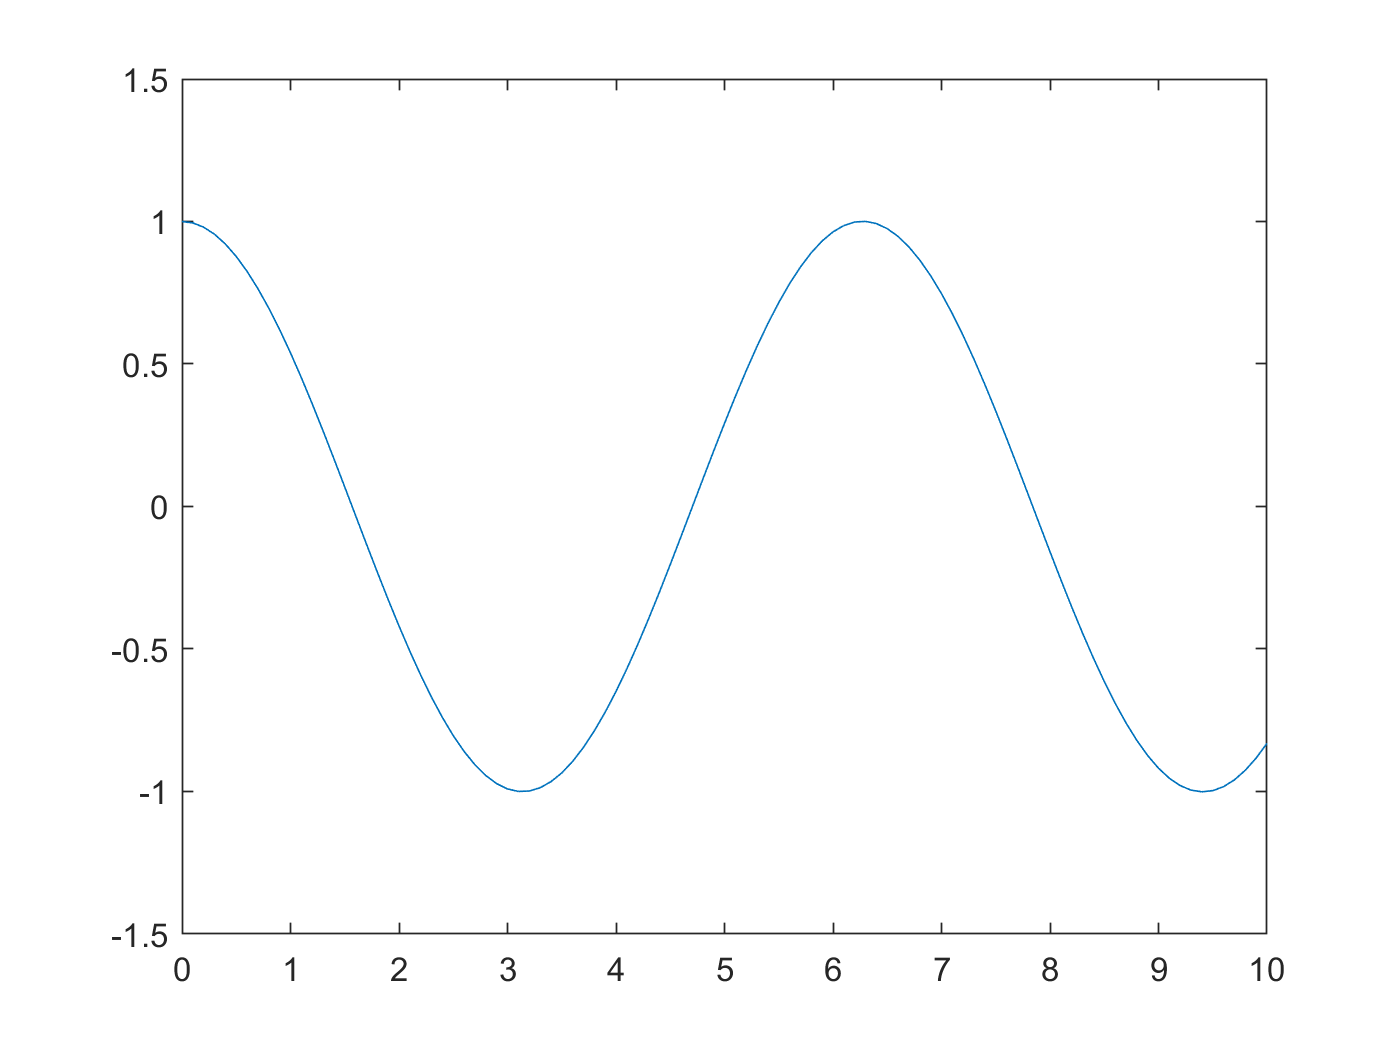




plot(t,x)

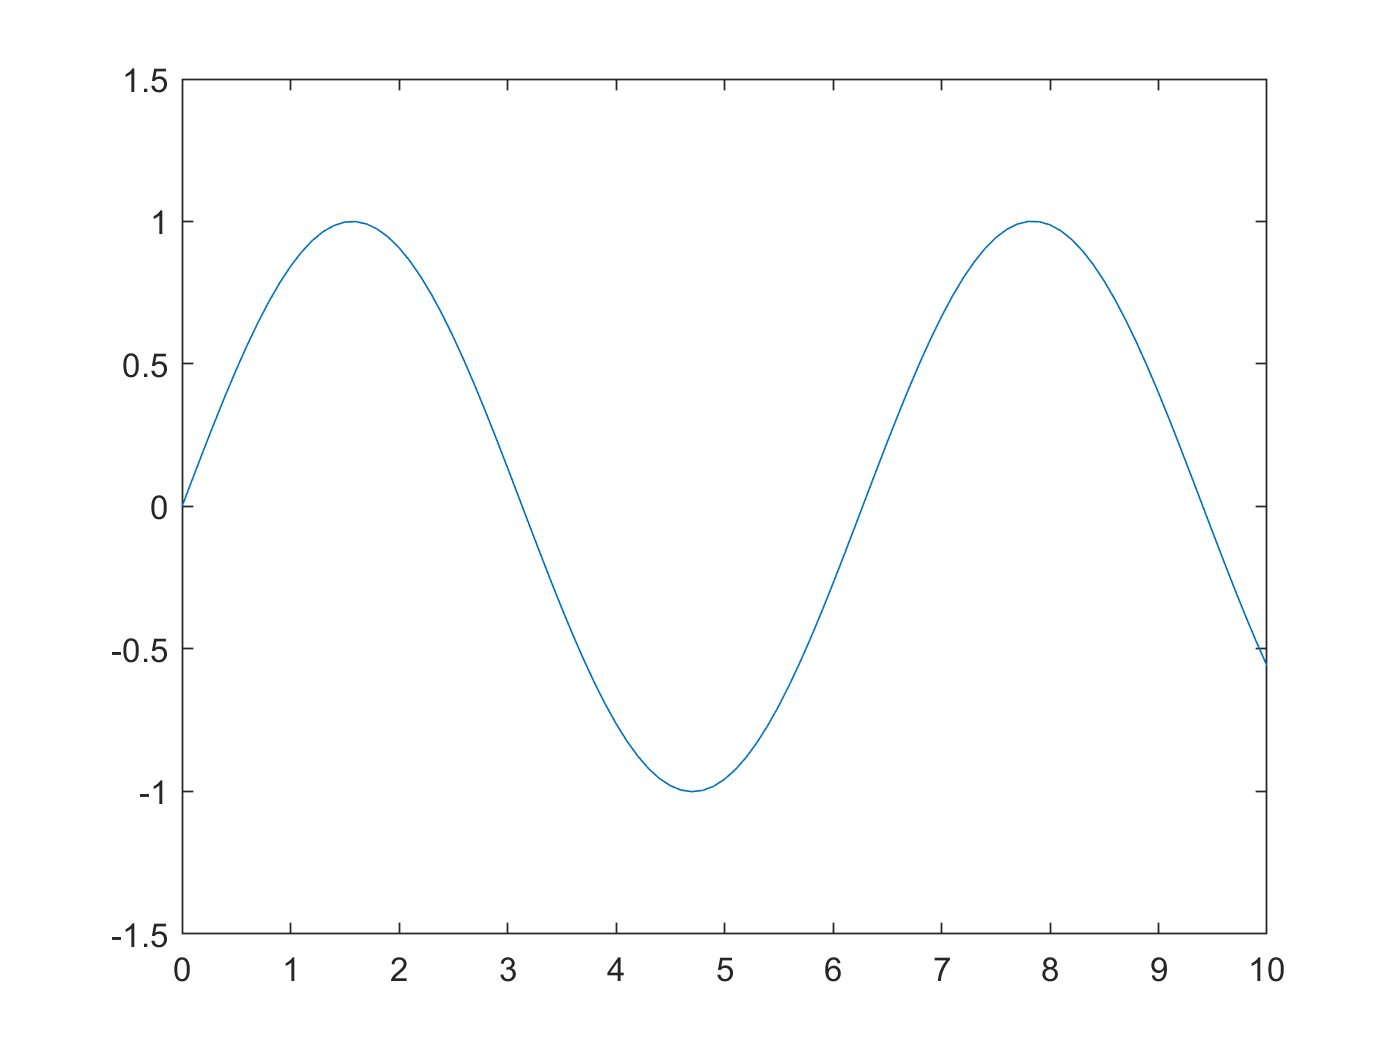


plot(t,y)

Functions

function [x,y,t] = EMsolver(e,f,g,h,x_0,y_0,T,N)
 A = [e f; g h];
 dt = T/N;
 t = 0:dt:T;

 SOL = NaN(2,length(t));
 SOL(1,1) = x_0;
 SOL(2,1) = y_0;

 for(k = 2:length(t))
    SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
 end

 x = SOL(1,:);
 y = SOL(2,:);
end

function [x,y,t] = IEMsolver(e,f,g,h,x_0,y_0,T,N)
    A = [e f; g h]
    dt = T/N
    t = 0:dt:T;
    
    SOL = NaN(2,length(t));
    SOL(1,1) = x_0;
    SOL(2,1) = y_0;
    
     for(k = 2:length(t))
        %SOL(:,k) = SOL(:,k-1) + 0.5 * (dt*A*SOL(:,k-1) + SOL(:,k-1) + dt*A*SOL(:,k-1));
        SOL(:,k) = SOL(:,k-1) + 0.5*(dt * A * SOL(:,k-1) + dt*A*(SOL(:,k-1) + dt*A*SOL(:,k-1)));
     end
     
     x = SOL(1,:);
     y = SOL(2,:);
end